d =  [6e-06 -1.7e-05 4e-06 -4e-06 0 1.9e-05 -5e-06 5e-06]';

% Construct system matrix for the ray path models
s2=sqrt(2);
G = [1,0,0,1,0,0,1,0,0;
     0,1,0,0,1,0,0,1,0;
     0,0,1,0,0,1,0,0,1;
     1,1,1,0,0,0,0,0,0;
     0,0,0,1,1,1,0,0,0;
     0,0,0,0,0,0,1,1,1;
     s2,0,0,0,s2,0,0,0,s2;
     0,0,0,0,0,0,0,0,s2];

% Get the singular values for the system matrix
[U,S,V] = svd(G);

[m,n] = size(G);

%rank
p=rank(G);


### N0.1 Find the trace of Rm

% model resolution matrix
Vp=V(:,1:p);
Rm=Vp*Vp';

trace_Rm = trace(Rm)

trace_Rm = 7.0000

### Plot $R_{m}$

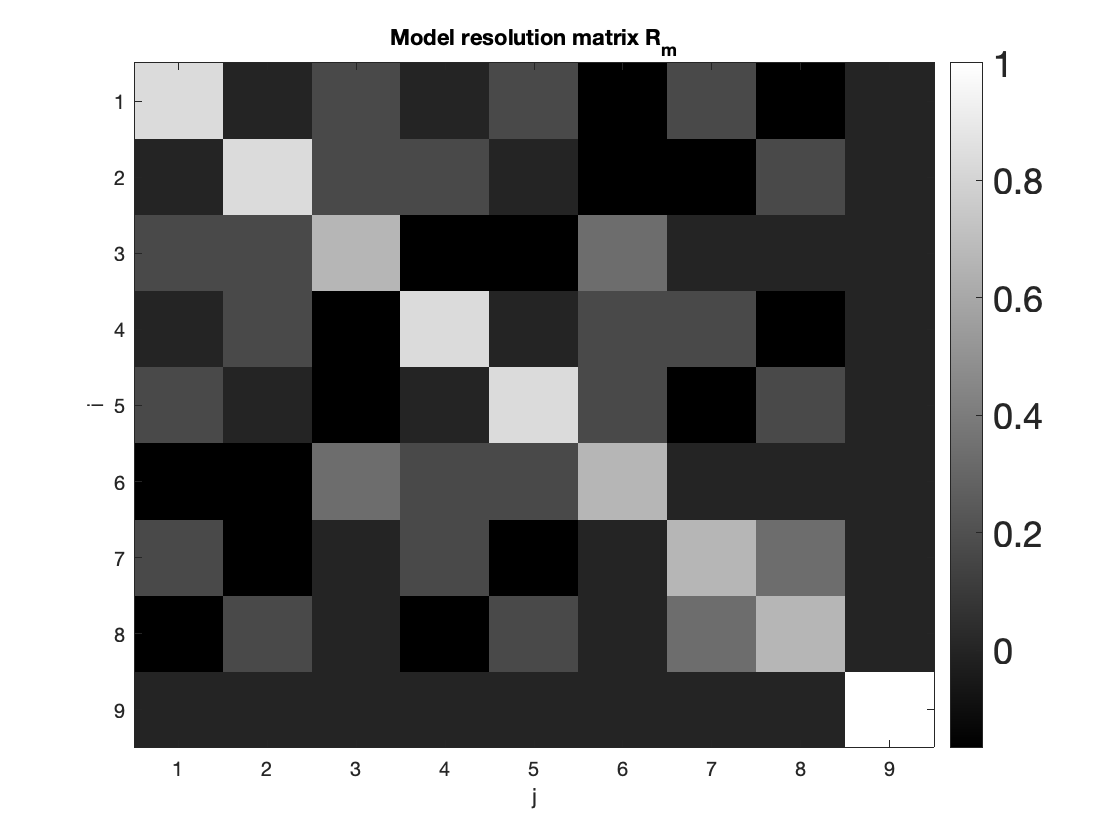


figure(13)
clf
colormap('gray')

imagesc(Rm)
set(colorbar,'Fontsize',18);
set(gca,'xtick',[1,2,3,4,5,6,7,8,9]);
set(gca,'ytick',[1,2,3,4,5,6,7,8,9]);
xlabel('j')
ylabel('i')
title('Model resolution matrix R_{m}')

### Discuss how good the model resolution is.

Based on the model resolution matrix plot, and the Rmdiag matrix below, its clear that $m_{9}$ is 1, hence it is perfectly resolved, however we can expect loss of resolution as a result of smearing the true model into other off diagonal blocks as shown in the figure above. The trace($R_{m}$) not being equal to n=9 also exposes the fact that the true model is not perfecly resolved.

Rmdiag=reshape(diag(Rm),3,3)'

Rmdiag =     0.8333    0.8333    0.6667
    0.8333    0.8333    0.6667
    0.6667    0.6667    1.0000


### N0.2 Plot $R_{d}$

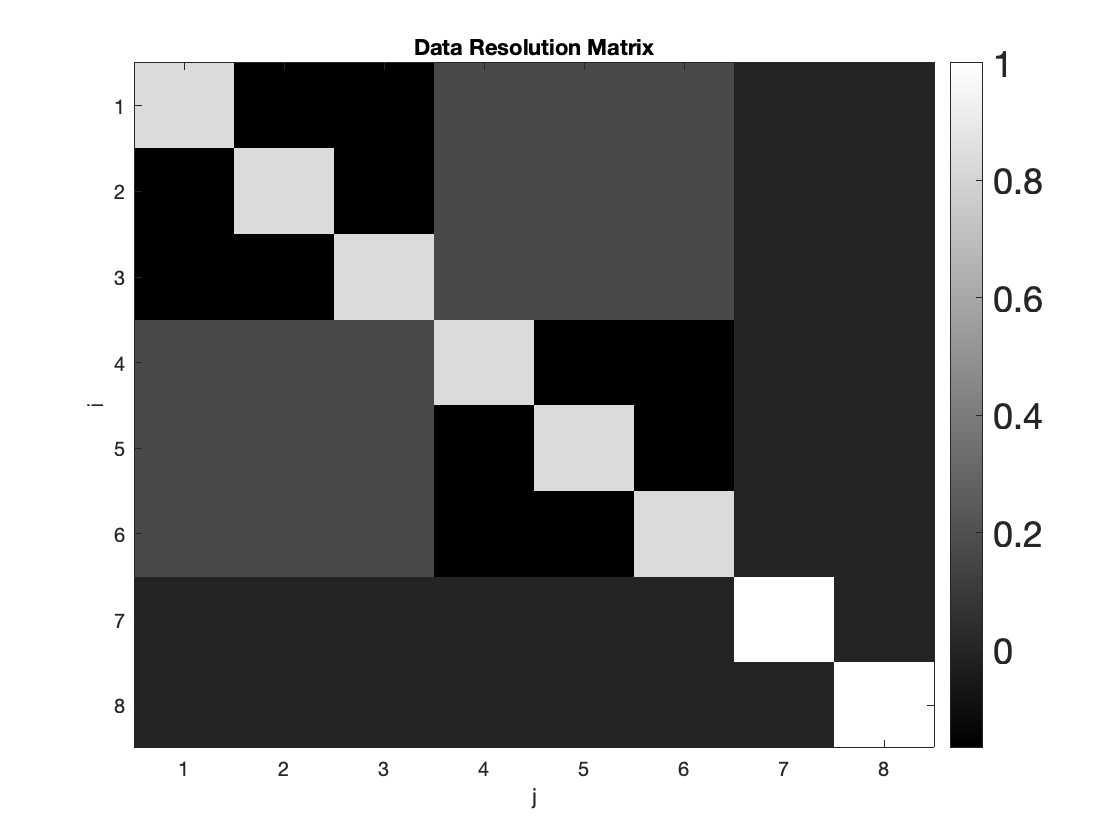

Gdagger = V(:,1:p)*inv(S(1:p,1:p))*U(:,1:p)';

Rd = G*Gdagger;

figure(10)
clf
colormap('gray')
imagesc(Rd)
%caxis([-0.1 1.0])
set(colorbar,'Fontsize',18);
set(gca,'xtick',[1,2,3,4,5,6,7,8,9]);
set(gca,'ytick',[1,2,3,4,5,6,7,8,9]);
xlabel('j')
ylabel('i')
title('Data Resolution Matrix')

### find the trace of Rd

trace_Rd = trace(Rd)

trace_Rd = 7.0000

### Discuss how good the data resolution is

According to the plot of $R_{d}$ above and the Rddiag matrix beow, it shows that the last two data points are perfectly resolved, and also the remaing diagnol points of $R_{d}$ as they are near 1, however, there is loss of resolution in off diagonal elements due to true data being smeared to other blocks. The trace($R_{d}$) being not close  to m=8, also exposes poor data resolution. 

Rddiag=reshape(diag(Rd),4,2)'

Rddiag =     0.8333    0.8333    0.8333    0.8333
    0.8333    0.8333    1.0000    1.0000


### N0.3 Verify that $R_{m} -I$ $= -V_{o}V_{o}^{T}$ 

Rmi = Rm - eye(n)

Rmi =    -0.1667         0    0.1667    0.0000    0.1667   -0.1667    0.1667   -0.1667   -0.0000
         0   -0.1667    0.1667    0.1667    0.0000   -0.1667   -0.1667    0.1667   -0.0000
    0.1667    0.1667   -0.3333   -0.1667   -0.1667    0.3333    0.0000    0.0000    0.0000
    0.0000    0.1667   -0.1667   -0.1667   -0.0000    0.1667    0.1667   -0.1667   -0.0000
    0.1667    0.0000   -0.1667   -0.0000   -0.1667    0.1667   -0.1667    0.1667   -0.0000
   -0.1667   -0.1667    0.3333    0.1667    0.1667   -0.3333    0.0000    0.0000    0.0000
    0.1667   -0.1667    0.0000    0.1667   -0.1667    0.0000   -0.3333    0.3333    0.0000
   -0.1667    0.1667    0.0000   -0.1667    0.1667    0.0000    0.3333   -0.3333    0.0000
   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000


Vo = [V(:,8) V(:,9)];
VV = -(Vo*Vo')

VV =    -0.1667   -0.0000    0.1667    0.0000    0.1667   -0.1667    0.1667   -0.1667    0.0000
   -0.0000   -0.1667    0.1667    0.1667    0.0000   -0.1667   -0.1667    0.1667    0.0000
    0.1667    0.1667   -0.3333   -0.1667   -0.1667    0.3333    0.0000    0.0000   -0.0000
    0.0000    0.1667   -0.1667   -0.1667   -0.0000    0.1667    0.1667   -0.1667   -0.0000
    0.1667    0.0000   -0.1667   -0.0000   -0.1667    0.1667   -0.1667    0.1667   -0.0000
   -0.1667   -0.1667    0.3333    0.1667    0.1667   -0.3333    0.0000   -0.0000    0.0000
    0.1667   -0.1667    0.0000    0.1667   -0.1667    0.0000   -0.3333    0.3333   -0.0000
   -0.1667    0.1667    0.0000   -0.1667    0.1667   -0.0000    0.3333   -0.3333    0.0000
    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000


verify = isequal(Rmi,VV)

verify = logical
   0


### Calculate the norm

Norm_bias = norm(Rmi)

Norm_bias = 1.0000

### Discuss how this matrix gives an indication of the bias in parameter estimates.

The norm($R_{m} -I$) must be approximate to  (trace($$R_{m}$$) - n) to quantify bias in the parameter estimates, however for this example  norm($R_{m} -I$)  = 1 and trace($$R_{m}$$) - n = -2, which are not equal, hence there is no bias in the parameter estimates.

t_rm = trace_Rm - n

t_rm = -2.0000

### N0.4 Plot the recovered models.

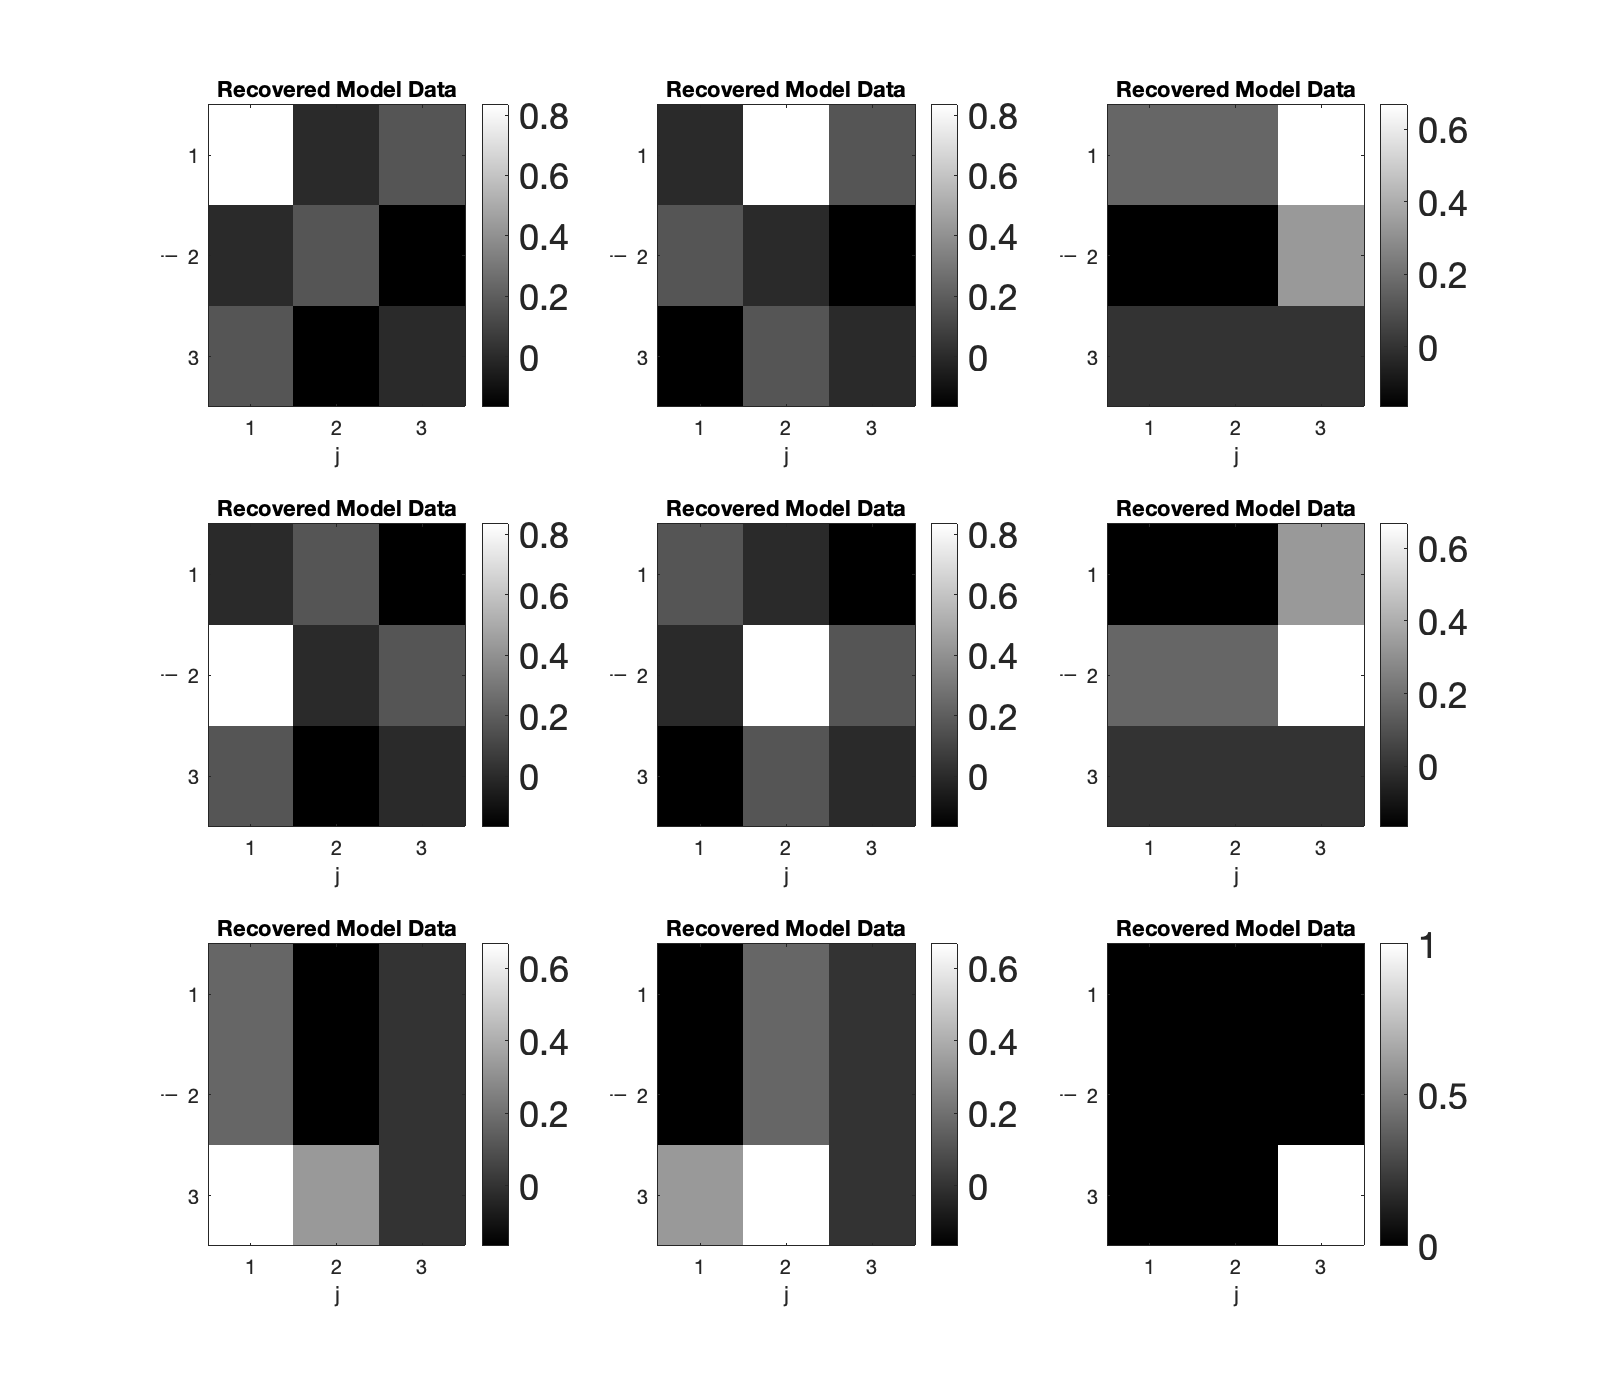

% Spike resolution test
figure(4)
for i = 1:9
    % Construct spike model
    mtest=zeros(n,1);

    mtest(i)=1;
    
    % Get noise free data for the spike model (forward problem)
    dtest=G*mtest;
    
    mdagger=pinv(G)*dtest;
    
    subplot(3, 3, i) ;

    colormap('gray')
    imagesc(reshape(mdagger,3,3)');
    %caxis([-0.1 1.0])
    set(colorbar,'Fontsize',18);
    set(gca,'xtick',[1,2,3]);
    set(gca,'ytick',[1,2,3]);
    xlabel('j')
    ylabel('i')
    title('Recovered Model Data')
end
set(gcf,'Position',[600,600,850,700])

### Conclusion about the smaering of the parameter estimates due to limited data resolution.

It causes data about the central block slowness to smear into some but not all of the adjacent blocks  with the exact form of smearing depicted in the model resolution matrix.

### N0.5 Find the condition numbers of G and $G^{\dagger}$

C_G = cond(G)

C_G = 2.8063e+16

C_Gdagger = cond(Gdagger)

C_Gdagger = 3.0889e+16

### Stability of model parameter estimates in relation to condition numbers of G and $G^{\dagger}$

Since the condition number for both G and $G^{\dagger}$are big, then it means that  model parameteres produced by using both G and $G^{\dagger}$ are instable, since we have a significant parameter change dipicted from the fact that in both scenarios, $s_{1} >> s_{p}$, producing very large condition numbers, hence telling as that we are dealing with an ill-conditioned problem.